% Example Input (Replace with actual data)
flattened_surface = obj_2D.vt;  % Flattened 2D vertex positions
deployed_surface = obj_3D.v;    % Deployed 3D vertex positions
faces = obj_2D.f.v;             % Face connectivity
deployed_surface = [deployed_surface(:,1), deployed_surface(:,3),deployed_surface(:,2)]  

deployed_surface =   -50.0000         0         0
  -49.9748   -1.5870    0.0504
  -49.8992   -3.1725    0.1008
  -49.7781   -4.7030    0.1494
  -49.6020   -6.2931    0.2000
  -49.3954   -7.7481    0.2462
  -49.1461   -9.1963    0.2922
  -48.8544  -10.6366    0.3380
  -48.5203  -12.0677    0.3834
  -48.1444  -13.4884    0.4286


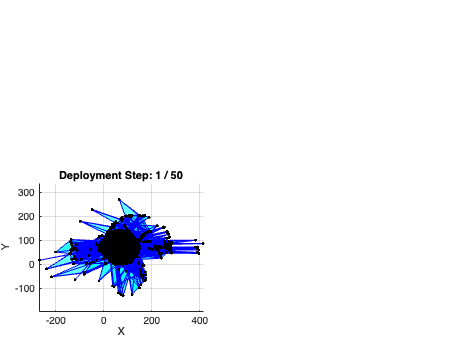

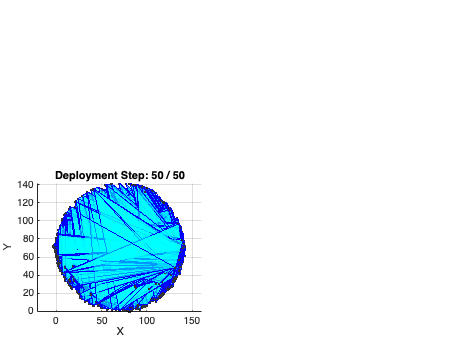

flattened_surface = [flattened_surface,zeros(size(flattened_surface,1),1)];
numFrames = 50; % Number of deployment steps
alpha = linspace(0,1,numFrames); % Deployment parameter

% Compute edge vectors in both configurations
vector_flattened_1 = flattened_surface(faces(:,2), :) - flattened_surface(faces(:,1), :);
vector_flattened_2 = flattened_surface(faces(:,2), :) - flattened_surface(faces(:,3), :);
vector_deployed_1 = deployed_surface(faces(:,2), :) - deployed_surface(faces(:,1), :);
vector_deployed_2 = deployed_surface(faces(:,2), :) - deployed_surface(faces(:,3), :);

% Compute transformation vectors for each edge
displacement_vector_1 = vector_deployed_1 - vector_flattened_1;
displacement_vector_2 = vector_deployed_2 - vector_flattened_2;

% Set up figure
fig = figure('Color', 'w');
axis equal; grid on;
xlabel('X'); ylabel('Y'); zlabel('Z');
view(45, 30);
hold on;

% Deployment Animation Loop
for k = 1:numFrames
    % Interpolate edge vectors
    vector_interp_1 = vector_flattened_1 + alpha(k) * displacement_vector_1;
    vector_interp_2 = vector_flattened_2 + alpha(k) * displacement_vector_2;

    % Reconstruct vertices using interpolated edges
    V_deploy = flattened_surface; % Start with initial configuration
    for i = 1:size(faces,1)
        V_deploy(faces(i,2), :) = V_deploy(faces(i,1), :) + vector_interp_1(i,:);
        V_deploy(faces(i,3), :) = V_deploy(faces(i,1), :) + vector_interp_2(i,:);
    end
    
    % Clear figure and plot new deployment state
    clf;
    patch('Vertices', V_deploy, 'Faces', faces, ...
          'FaceColor', 'cyan', 'EdgeColor', 'b', 'FaceAlpha', 0.6);
    
    hold on;
    plot3(V_deploy(:,1), V_deploy(:,2), V_deploy(:,3), 'k.'); % Mesh points
    hold off;

    % Axis settings
    axis equal; grid on;
    xlabel('X'); ylabel('Y'); zlabel('Z');
    title(['Deployment Step: ' num2str(k) ' / ' num2str(numFrames)]);


    drawnow;
end


disp('Deployment animation complete.');

Deployment animation complete.
